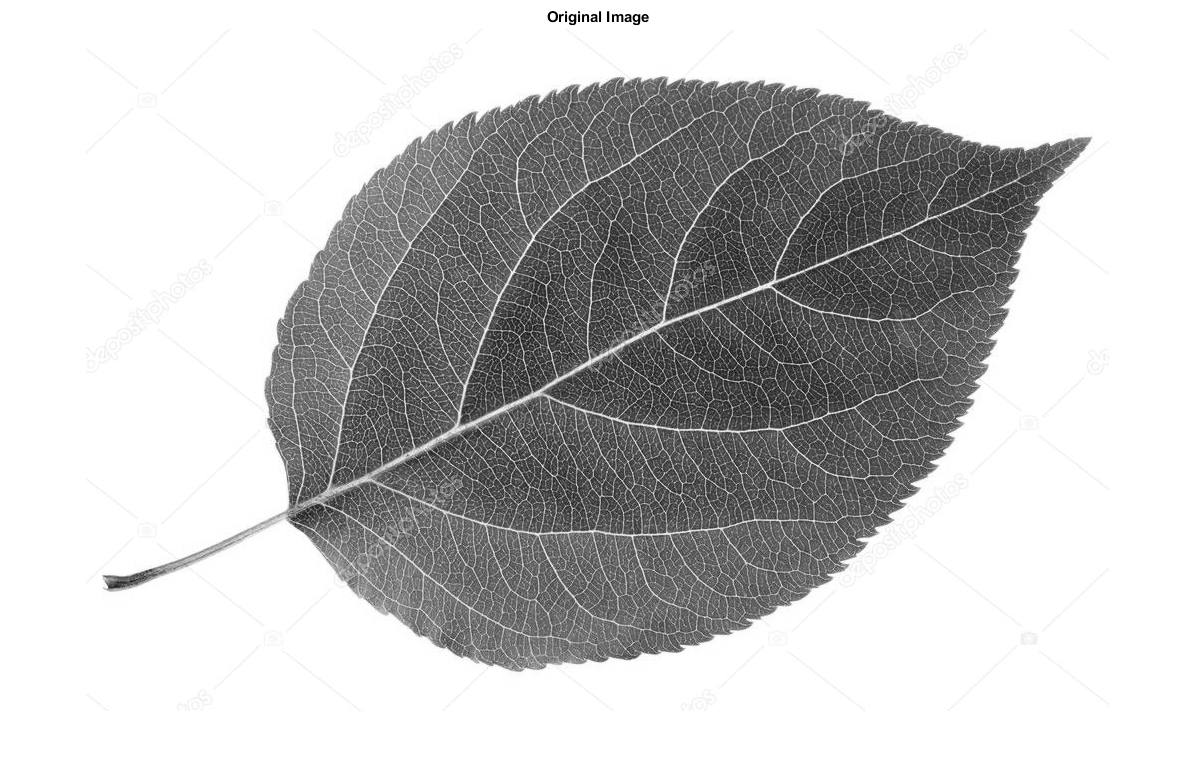

image = double(rgb2gray(imread('leaf.jpg')));
figure, imshow(mat2gray(image)),  title("Original Image");

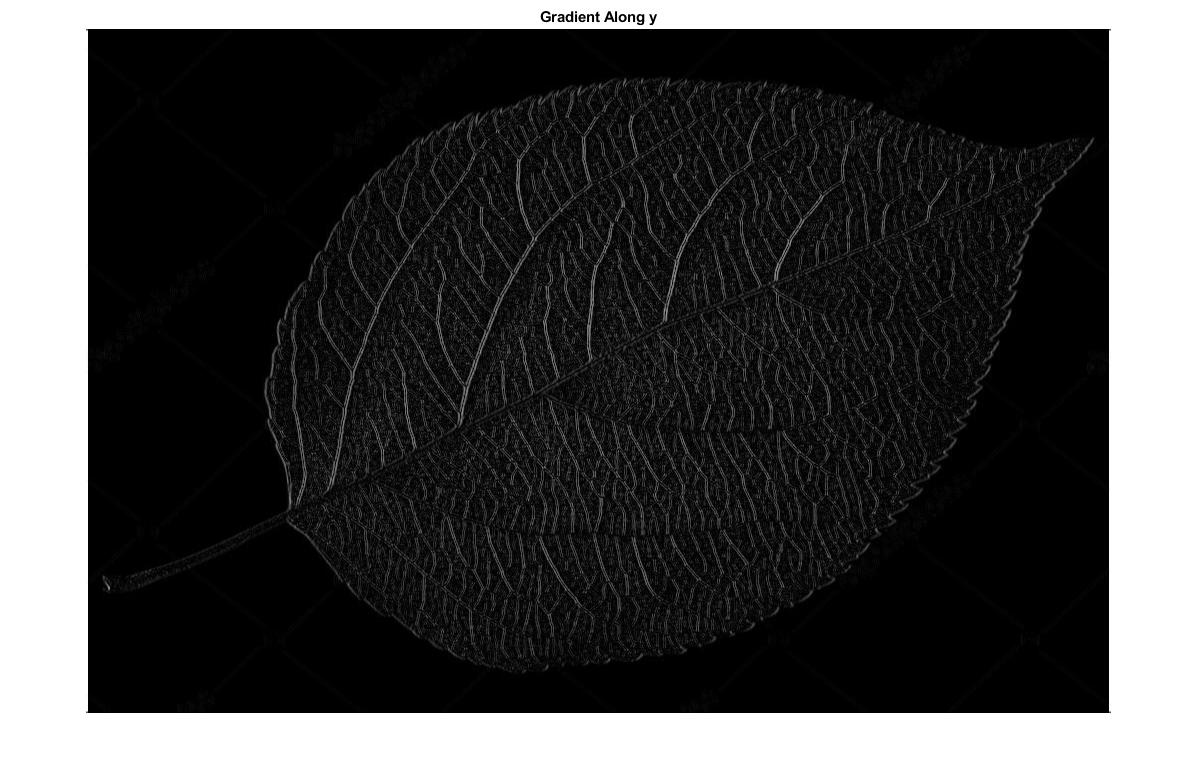


% Prewitt Filters
prewitt_Gx = [-1 0 1; -1 0 1; -1 0 1];
prewitt_Gy = [1 1 1; 0 0 0; -1 -1 -1];


Ex = abs(my_conv2d(image, prewitt_Gx ));
Ey = abs(my_conv2d(image, prewitt_Gy));

figure, imshow(mat2gray(Ex)), title("Gradient Along y");

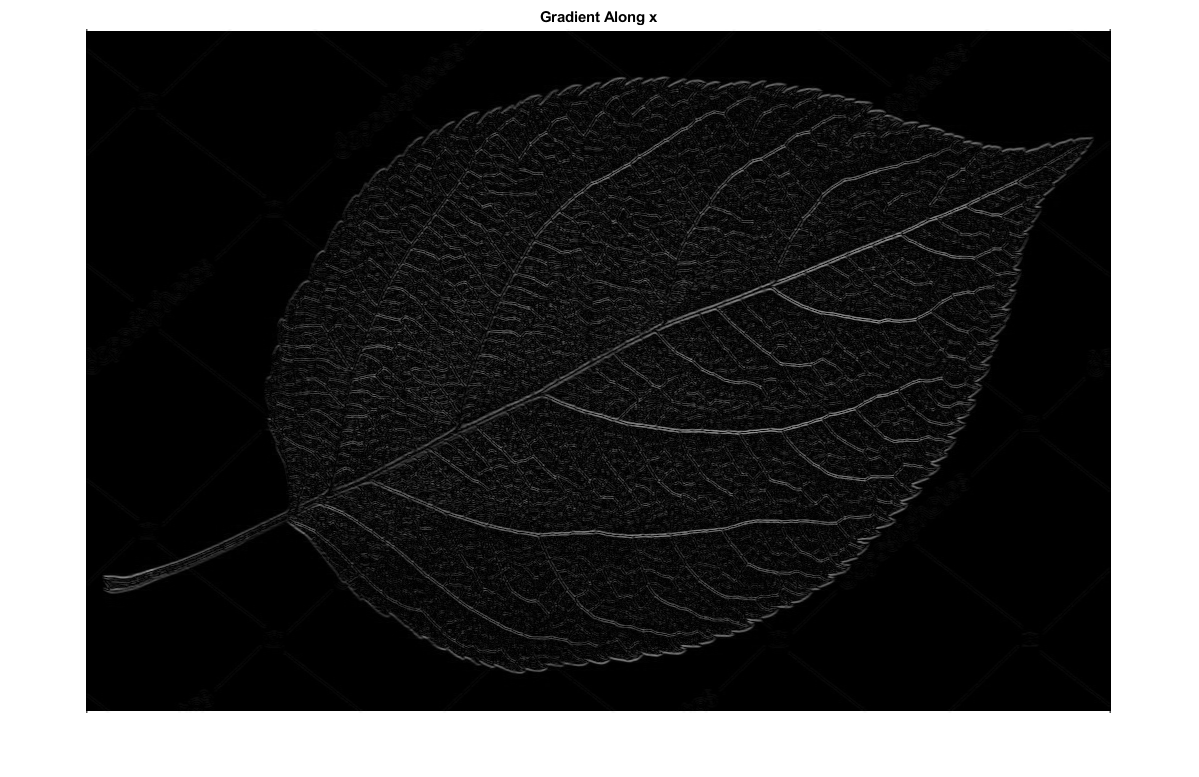

figure, imshow(mat2gray(Ey)), title("Gradient Along x")

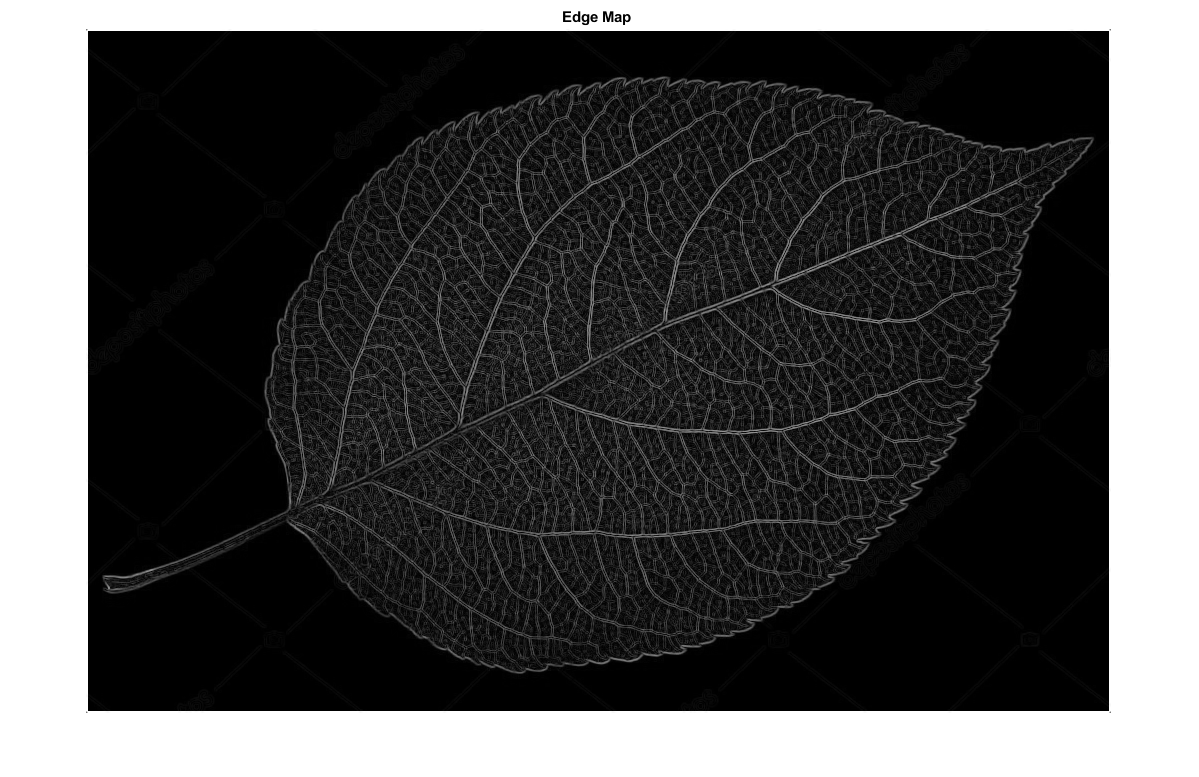


E = sqrt(Ex.^2 + Ey.^2);
figure, imshow(mat2gray(E)),title("Edge Map ");

function g_x = my_conv2d(f_x, kernel)
[r0,c0] = size(f_x);
[r1, c1] = size(kernel);
r2 = r0 + r1 - 1; %final rows of the convoluted matrix
c2 = c0 + c1 - 1; %final columns of the convoluted matrix
f_x = padarray(f_x,[r1,c1],0,"both"); %padding to ensure any boundary conditions
kernel_rot = zeros(r1,c1);

%this part rotates the kernel by 180 degress
for i=1:r1
    for j=1:c1
        kernel_rot(r1-i+1,c1-j+1) = kernel(i,j);
    end
end

%aligning the centres of the kernel and the padded matrix and performing
%the element wise matrix  multiplication operation.
g_x = zeros(r2,c2);
for i=r1 - floor(r1/2)+1:r0+r1+floor(r1/2)
    for j=c1 - floor(c1/2)+1:c0+c1+floor(c1/2)
        sub_matrix = f_x((i-floor((r1-1)/2)):(i+floor(r1/2)), (j-floor((c1-1)/2)):(j+floor(c1/2)));
        val = sub_matrix.*kernel_rot;
        sum_ = sum(val(:));
        g_x(i-2,j-2) = sum_;
        
    end
end
g_x=g_x(1:r2, 1:c2);
end